% Curve Fitting 
% used least square method method.
% Author: Helal Uzzaman Hasib
% Date: 20 Jun 2023
% ======================================================

disp('Curve fitting nth order polynomial least square method')

Curve fitting nth order polynomial least square method


clc
clear
%Example 1
x = [0 1 2];
y = [1 6 17];
n = 2;
%Example 2
% x = [0 2 5 7];
% y = [-1 5 12 20];
% n = 1;
%Example 3
x = [1 3 4 6];
y = [ .63 2.05 4.08 10.78];
n = 2;
x = input('Enter x values:\n ');
y = input('Enter y values:\n ');
n = input('Enter order: \n ');

n = n+1;
A = zeros(n,n)

A =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


B = zeros(n,1)

B =      0
     0
     0
     0
     0
     0
     0
     0
     0


sumY = sum(y);
for i= 1:n
   for j = 1:n
%        fprintf('row %d col%d\n', i, j);
       A(i,j)= sum(x.^(i+j-2));
   end
    
   B(i) =sum(x.^(i-1).*y);
end
result = gaussElimination(A,B);
nn = length(x);
equation = flip(result)

equation =    -0.0080    0.0003   -0.0260    0.1135    0.4945    0.6549   -2.3282    6.0989    1.0000


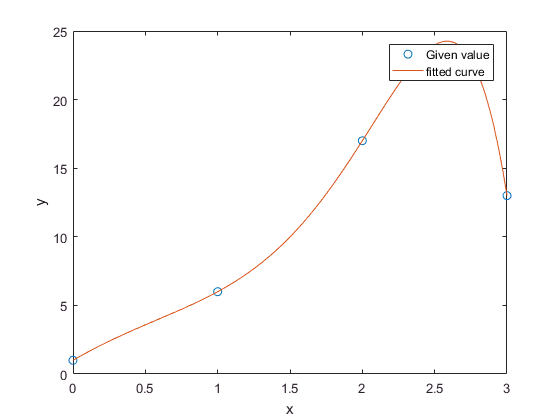

%plotting
xx = linspace(x(1), x(nn), 100);
yy = polyval(equation, xx);
plot(x,y, 'o')
hold on;
plot(xx, yy)
legend('Given value', 'fitted curve');
xlabel('x'); ylabel('y');
hold off;